# iPhone LiDARで取得した3次元点群の境界を書き出してみよう

この記事は、MATLABアドベントカレンダーxx日目の記事として書かれています。

https://qiita.com/advent-calendar/2022/matlab

この記事では、iPhone LiDARで取得した3次元点群をMATLABにて読み込み、さらに、その領域の境界のデータをKMLファイルとして出力する方法を紹介します。言語はMATLABを使用します。

3次元点群を取得するためのアプリは3D Scanner Appを用いました。

詳しい使い方は、以下の記事がわかりやすかったです。ここでは、すでにiPad LiDARにて計測し、PCに転送した状態から始めます。

https://note.com/iwamah1/n/n9b1c39ed7e70

なお、ここで用いたコードや、点群ファイルは以下のページにアップロードされています。

[https://github.com/KentaItakura/Plot-iPhone-LiDAR-data-in-3D-basemap-using-MATLAB](https://github.com/KentaItakura/Plot-iPhone-LiDAR-data-in-3D-basemap-using-MATLAB)

## 点群ファイルの読み込み

LiDAR toolboxの機能を用いて、点群データの読み込みを行います。以下のように、`lasFileReader`や`readPointCloud`関数を用いて、簡単に点群ファイルを読み込むことができます。まずは、GPS情報を有した点群（LAS）ファイルをそのまま読み込み、表示してみます。

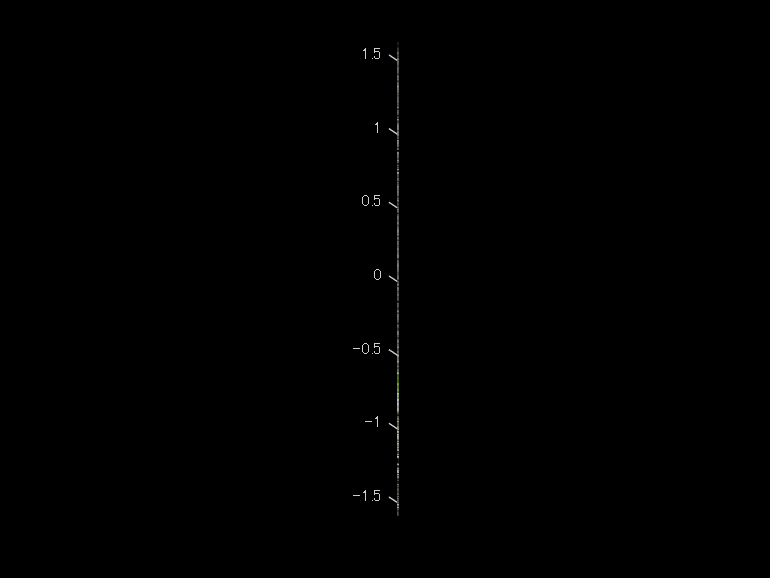

clear;clc;close all
% las/lazファイルを読み込むためのlasFileReader objectを作成する
lasReader = lasFileReader('sample.las');
% las/lazファイルの、xyzおよび色情報を読み込み
ptCloud = readPointCloud(lasReader);
% 可視化
figure;pcshow(ptCloud)

このように、うまく表示できません。2022年12月現在、3D Scanner Appから、Geo-referenceされたLASファイルをエキスポートすると、その座標は経度・緯度の値を持っています。経度緯度の値は、小数点以下の数が非常に多く、単にビューワーに読み込むだけではうまく行かない場合も多いです。

## 座標系の変換

### geocrsオブジェクトの作成

MATLABのpcshow関数で、点群を閲覧するために経度緯度のxy座標を投影座標に変換します。

% geojcrsオブジェクトを作成する
geocrs4326 = geocrs(4326);

ここで、作成した、geocrsオブジェクトの中身について確認します。

% 確認のため、geocrsを表示
disp(geocrs4326)

  geocrs のプロパティ:

             Name: "WGS 84"
            Datum: "World Geodetic System 1984"
         Spheroid: [1×1 referenceEllipsoid]
    PrimeMeridian: 0
        AngleUnit: "degree"



測地系（Datum）の情報や、Spheroid（楕円体）の情報格納されています。

PrimeMeridianは、本初子午線のことで、ここの数字は、緯度の基準が旧グリニッジ天文台からどれくらいの差分があるかを示しています。今回は0なので特に気にする必要はありません。

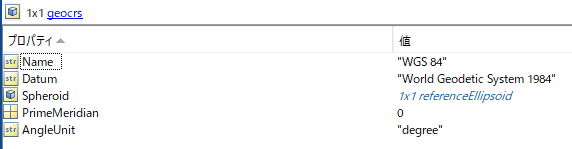

また、Spheroidをクリックすると、その中身を確認することができます。

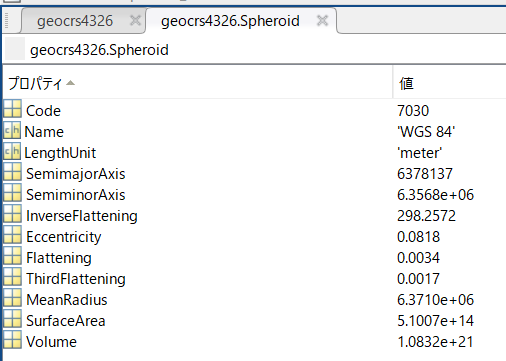

一部のみを紹介します。

- Code: 割り当てられている識別コード EPSG:7030

- SemimajorAxis: 赤道半径 6,378,137 m

- InverseFlattening: 扁平率の逆数 298.257223563

扁平率とは、（今回は）地球を表す楕円体が、完全な球と比べた時にどれくらい、扁平であるか（つぶれているか）を示します。全くつぶれていない（＝球と同じ）場合は、0となり、つぶれているほど、1に近づきます。

楕円体の長半径をa、短半径をbとすると、扁平率は、


$$1-\frac{b}{a}\;=\frac{a-b}{a}\;$$


で表すことができます。

実際にその逆数を計算してみると、

f = 1-geocrs4326.Spheroid.SemiminorAxis/geocrs4326.Spheroid.SemimajorAxis;
1/f

ans = 298.2572

となり、InverseFlatteningの値と一致することが確認できます。

また、`geocrs`オブジェクトを用いて、そのWKTを簡単に作成することもできます。

WKT（Well-Known Text）は、ジオメトリの情報をテキスト形式で記述するものです。

str = wktstring(geocrs4326)

str = "GEOGCRS["WGS 84",DATUM["World Geodetic System 1984",ELLIPSOID["WGS 84",6378137,298.257223563,LENGTHUNIT["metre",1]]],PRIMEM["Greenwich",0,ANGLEUNIT["degree",0.0174532925199433]],CS[ellipsoidal,2],AXIS["geodetic latitude (Lat)",north,ORDER[1],ANGLEUNIT["degree",0.0174532925199433]],AXIS["geodetic longitude (Lon)",east,ORDER[2],ANGLEUNIT["degree",0.0174532925199433]],USAGE[SCOPE["Horizontal component of 3D system."],AREA["World."],BBOX[-90,-180,90,180]],ID["EPSG",4326]]"

ここでも、さきほどの、`geocrs`オブジェクトのような情報が確認できます。

### projfwd関数を用いた、座標の変換

それでは、経度緯度の座標を投影座標に変換したいと思います。

このサンプルデータは、東京都で取得されたため、EPSGコードは6676を利用します。

変換自体は、`projfwd`関数を用いて簡単に行うことができます。

lon = ptCloud.Location(:,1);
lat = ptCloud.Location(:,2);
proj = projcrs(6676);
[x,y] = projfwd(proj,lat,lon);

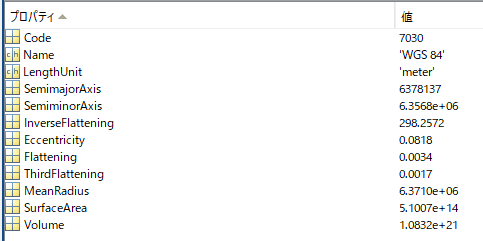

[https://qiita.com/tohka383/items/2b22dfdd442f987b6714](https://qiita.com/tohka383/items/2b22dfdd442f987b6714)

## 3次元マップでの点群の可視化

さきほどは、地図上にて、点群を可視化しましたが、2次元のマップであったため、各点の位置やその上からの様子を知るということに限定されていました。これでは、iPhone LiDARで取得した3次元情報をうまく可視化できているとは言えません。このセクションでは、iPhone LiDARで取得した点群を、3次元のマップ上で可視化してみます。

% 25点のうち1点のみを表示する。重くなってしまうため。
mskip = 1:50:length(lat);
% 3Dで可視化するための図を用意する
uif = uifigure;
g = geoglobe(uif);
% プロット
geoplot3(g,lat,lon,ptCloud.Location(:,3)-mean(ptCloud.Location(:,3)),'r','MarkerSize',2,'Marker','o','HeightReference','terrain','LineStyle','none','MarkerIndices',mskip)

このように、3Dの地図（ベースマップ）上で、iPhone LiDARの点群を可視化することができました。

色はうまく表示できていませんが、ベースマップ上でどのような点群が取得されたかを確認することができます。

いくつか注意点があるので記述します。

- `r:` プロットの色。各点を実際の3Dの色付けを行うことができない。指定した1つの色のみの可視化になる

- `'LineStyle','none'`: これにより、独立した点（線でない）をプロットできる

- `'HeightReference','terrain'`: 高さの基準を設定する。このほかに、`'geoid'` や`'ellipsoid'`が選択可能である。それぞれの違いについては、以下の図を参照して下さい。

- `'MarkerIndices'`にて間引きを行わないと、表示が非常の重くなるため注意する必要がある。

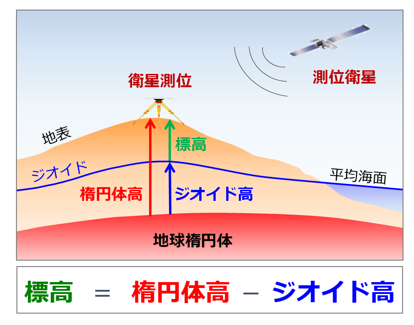

**図表出展: 国土地理院 ジオイドとは**

[https://www.gsi.go.jp/buturisokuchi/grageo_geoid.html](https://www.gsi.go.jp/buturisokuchi/grageo_geoid.html)

## kmlファイルへの書き込み

[https://jp.mathworks.com/help/map/ref/kmlwritepolygon.html](https://jp.mathworks.com/help/map/ref/kmlwritepolygon.html)

[https://jp.mathworks.com/help/map/ref/kmlwriteline.html](https://jp.mathworks.com/help/map/ref/kmlwriteline.html)

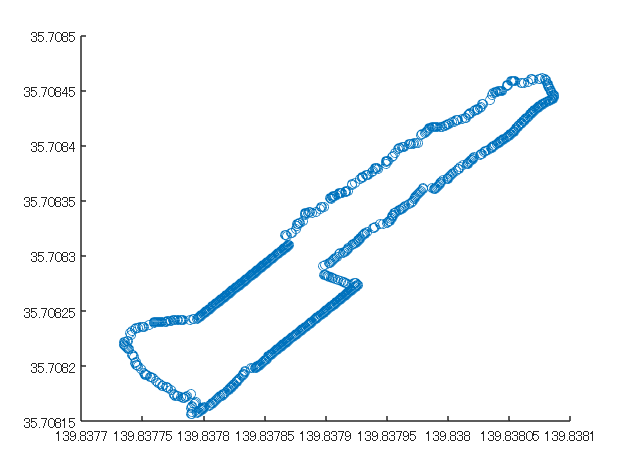

load coastlines
% Specify the name of output KML file that you want to create.
alt = 40;
filename = 'coastlines.kml';
k = boundary(lon,lat);
figure;scatter(lon(k),lat(k))

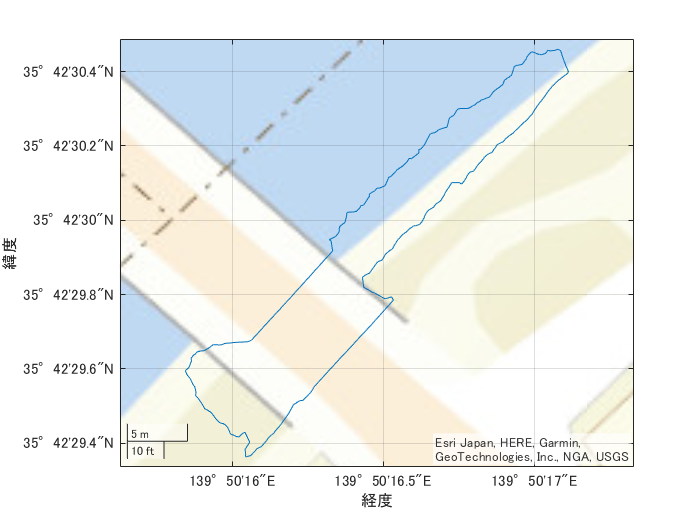

figure;geoplot(lat(k),lon(k))
geobasemap streets

## まとめ

- この記事では、iPhone LiDARで取得した点群をMATLABを用いて、地図上で可視化しました

- 投影座標系から経度・緯度への変換も簡単に行うことができました

- 3Dのベースマップ上で、点群を可視化することができました

- 表示する点数が多くなると、非常にビューワーが重くなるため、間引くことが必要です

## 参考にしたページ

[https://jp.mathworks.com/help/map/transform-coordinates-to-different-pcrs.html](https://jp.mathworks.com/help/map/transform-coordinates-to-different-pcrs.html)

[http://pen.envr.tsukuba.ac.jp/~torarimon/?%C2%AC%C3%CF%B7%CF%3A+datum](http://pen.envr.tsukuba.ac.jp/~torarimon/?%C2%AC%C3%CF%B7%CF%3A+datum)

Wikipedia: 扁平率

https://ja.wikipedia.org/wiki/%E6%89%81%E5%B9%B3%E7%8E%87

https://qiita.com/tohka383/items/2b22dfdd442f987b6714